% Autocorrelation
% Generate Profiles
warning('off')
mu = 0;
w = 1;           %Root mean square or Interface width
alpha = 0.5;     %Roughness exponent
%P = 6000;        %Number of points
% L = 1500; 
% xi = 10;
% P = 1*L;
% N = 100;       
% delta = L/P;   

stepSize = 100;

BM = NaN(19, 10);
BMad = BM;
E=BM;

BRef = NaN(10,1);
BMadRef = BRef;

CL = NaN(500, 100);

i = 1;
for xiRef_ = 10 : 10 : 50
    L = xiRef_*100;
    initialLength = xiRef_*30;
    P = 1*L;
    N = 50;       
    delta = L/P; 

    for j = 0 : (100/N - 1)
        [xi_, Profiles_] = generateRandomCorrelatedP(alpha, xiRef_, w, mu, P, L, N, 'exp', 'Autocorrelation');
        [x_, A_, sigma_] = GrowingWindow(delta, 0, Profiles_, ...
            stepSize, initialLength, 0, 'Autocorrelation');

        % [~, CL_Local] = correlationLength(1, A_, 0, '1/e');

        AB = errorBoundariesA(sigma_, A_);
        % [~, CL_Local] = correlationLength(1, AB, 0, 'powerLawFirstZeroPoint');
        % [~, CL_Local] = correlationLength(1, AB, 0, 'expFirstZeroPoint');
        [~, CL_Local] = correlationLength(1, AB, 0, '1/eExp');

        CL_Local_size = size(CL_Local);
        CL(1:CL_Local_size(1), (j*N)+1:(j+1)*N) = CL_Local;
    end
    CLs = size(x_); 

    CL = CL(1:CLs(1),:);
    
    BM(1:CLs(1), i) = median(x_./CL, 2, 'omitnan');
    BMad(1:CLs(1), i) = mad(x_./CL, 1, 2);
    
    % Change here
    xiRef = xi_(5);
    E(1:CLs(1), i) = abs(median(CL,2) - xiRef)/xiRef;

    pos = precisePosition(0.1, 1, E(1:CLs(1), i), 'False') + 1

    if isnan(pos)
        i = i + 1;
        continue
    end

    EInterpolation = linspace(round(pos), round(pos+1), 100);
    EPart = round(pos):round(pos+1);

    BInterpolation = interp1(EPart, BM(round(pos):round(pos+1),i), EInterpolation);
    DevInterpolation = interp1(EPart, BMad(round(pos):round(pos+1),i), EInterpolation);

    p = round(100*(pos-fix(pos)));

    if p == 0
        BRef(i) = BM(pos);
        BMadRef(i) = BMad(pos);
        i = i + 1;
        continue
    end

    BRef(i) = BInterpolation(p);
    BMadRef(i) = DevInterpolation(p);


    i = i + 1;
end

pos = 11.8900

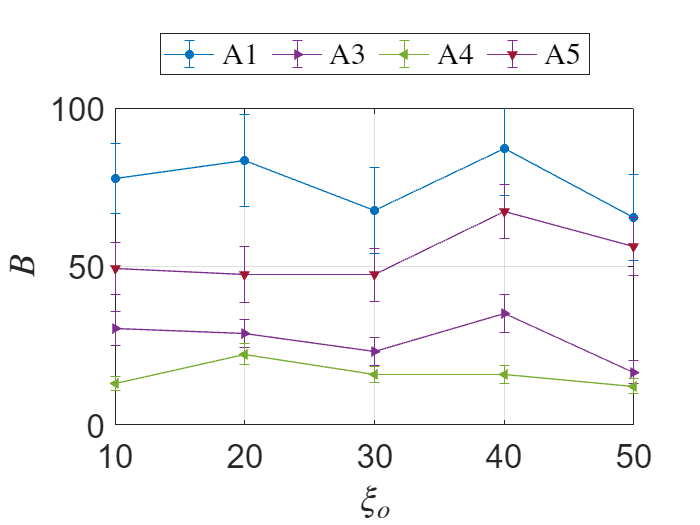

errorbar(r, B(1, :), BM(1, :), '-o', 'MarkerSize',5, 'MarkerFaceColor', "#0072BD", 'MarkerEdgeColor', "#0072BD", 'Color', "#0072BD"), hold on, grid on % 1/e
% errorbar(r, B(2, :), BM(2, :), '-d', 'MarkerSize',5, 'MarkerFaceColor', "#D95319", 'MarkerEdgeColor', "#D95319", 'Color',"#D95319") 
errorbar(r, B(3, :), BM(3, :), '->', 'MarkerSize',5, 'MarkerFaceColor', "#7E2F8E", 'MarkerEdgeColor', "#7E2F8E", 'Color',"#7E2F8E") 
errorbar(r, B(4, :), BM(4, :), '-<', 'MarkerSize',5, 'MarkerFaceColor', "#77AC30", 'MarkerEdgeColor', "#77AC30",'Color',"#77AC30")
errorbar(r, B(5, :), BM(5,:), '-v', 'MarkerSize',5, 'MarkerFaceColor', "#A2142F", 'MarkerEdgeColor', "#A2142F")
ylabel('$$B$$', 'FontSize', 22, 'Interpreter','latex')
xlabel('$$\xi_o$$', 'FontSize', 22, 'Interpreter','latex')
legend('A1', ...
    'A3', 'A4','A5', "Location", 'northoutside', 'Interpreter','latex', 'Orientation','horizontal')
ylim([0,100])
set(gca, 'FontSize', 20), hold off
saveas(gcf, 'BACF1.png')

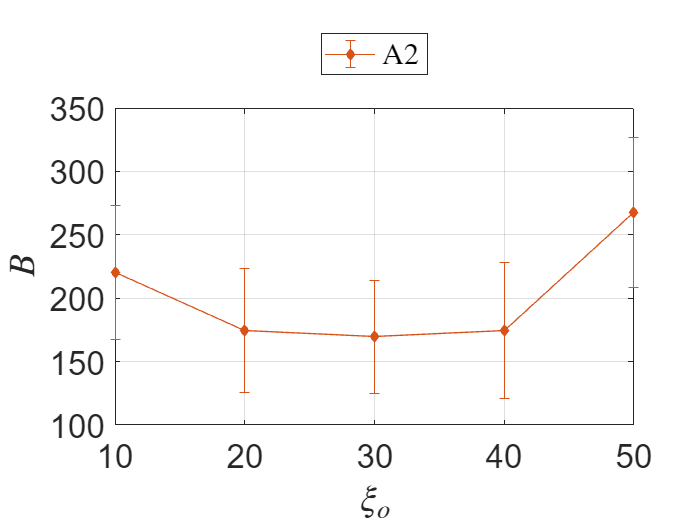

% errorbar(r, B(1, :), BM(1, :), '-o', 'MarkerSize',5, 'MarkerFaceColor', "#0072BD", 'MarkerEdgeColor', "#0072BD", 'Color', "#0072BD"), hold on, grid on 
errorbar(r, B(2, :), BM(2, :), '-d', 'MarkerSize',5, 'MarkerFaceColor', "#D95319", 'MarkerEdgeColor', "#D95319", 'Color',"#D95319"), hold on, grid on
% errorbar(r, B(3, :), BM(3, :), '->', 'MarkerSize',5, 'MarkerFaceColor', "#7E2F8E", 'MarkerEdgeColor', "#7E2F8E", 'Color',"#7E2F8E") 
% errorbar(r, B(4, :), BM(4, :), '-<', 'MarkerSize',5, 'MarkerFaceColor', "#77AC30", 'MarkerEdgeColor', "#77AC30",'Color',"#77AC30")
% errorbar(r, B(5, :), BM(5,:), '-v', 'MarkerSize',5, 'MarkerFaceColor', "#A2142F", 'MarkerEdgeColor', "#A2142F")
ylabel('$$B$$', 'FontSize', 22, 'Interpreter','latex')
xlabel('$$\xi_o$$', 'FontSize', 22, 'Interpreter','latex')
legend('A2', "Location", 'northoutside', 'Interpreter','latex', 'Orientation','horizontal')
% ylim([0,100])
set(gca, 'FontSize', 20), hold off
saveas(gcf, 'BACF2.png')

% Hurst
% Generate Profiles
warning('off')
mu = 0;
w = 1;           %Root mean square or Interface width
alpha = 0.5;     %Roughness exponent
%P = 6000;        %Number of points
% L = 1500; 
% xi = 10;
% P = 1*L;
% N = 100;       
% delta = L/P;   

% stepSize = 100;

BM = NaN(19, 10);
BMad = BM;
E=BM;

BRef = NaN(10,1);
BMadRef = BRef;

CL = NaN(500, 100);

i = 1;
for xiRef_ = 10 : 10 : 50
    L = xiRef_*100;
    initialLength = xiRef_*10;
    stepSize = xiRef_*10;
    P = 1*L;
    N = 50;       
    delta = L/P; 

    for j = 0 : (100/N - 1)
        [xi_, Profiles_] = generateRandomCorrelatedP(alpha, xiRef_, w, mu, P, L, N, 'exp', 'Hurst');

        [x_, H_, sigma_] = GrowingWindow(delta, 0, Profiles_, ...
            stepSize, initialLength, 0, 'Hurst');

        [~, o_, ~] = GrowingWindow(delta, 0, Profiles_, ...
            stepSize, initialLength, 0, 'InterfaceWidthValue');

        dH = size(H_);
        H = nan(dH);

        for ii = 1:dH(2)
            for jj = 1:dH(3)
                H(:, ii, jj) = H_(:, ii, jj)./(sqrt(2)*o_(ii, jj));
                % H(:, i, j) = H_(:, ii, jj)./o_(ii, jj); % in case of IW function
            end
        end

        % [~, CL_Local] = correlationLength(1, H, 1, 'crossover');
        % [~, CL_Local] = correlationLength(1, H, 1, 'scaleKink');
        
        % [~, CL_Local] = correlationLength(1, H, 1, 'practicalRange');
        [~, CL_Local] = correlationLength(1, H, 1, 'inversedExp');

        CL_Local_size = size(CL_Local);
        CL(1:CL_Local_size(1), (j*N)+1:(j+1)*N) = CL_Local;
    end
    CLs = size(x_);

    CL = CL(1:CLs(1),:);

    BM(1:CLs(1), i) = median(x_./CL, 2, 'omitnan');
    BMad(1:CLs(1), i) = mad(x_./CL, 1, 2);

    % Change here
    xiRef = xi_(4);
    E(1:CLs(1), i) = abs(median(CL,2,'omitnan') - xiRef)/xiRef;

    pos = precisePosition(0.1, 1, E(1:CLs(1), i), 'False') + 1

    if isnan(pos)
        i = i + 1;
        continue
    end

    EInterpolation = linspace(round(pos), round(pos+1), 100);
    EPart = round(pos):round(pos+1);

    BInterpolation = interp1(EPart, BM(round(pos):round(pos+1),i), EInterpolation);
    DevInterpolation = interp1(EPart, BMad(round(pos):round(pos+1),i), EInterpolation);

    p = round(100*(pos-fix(pos)));

    if p == 0
        BRef(i) = BM(pos);
        BMadRef(i) = BMad(pos);
        i = i + 1;
        continue
    end

    BRef(i) = BInterpolation(p);
    BMadRef(i) = DevInterpolation(p);


    i = i + 1;
end

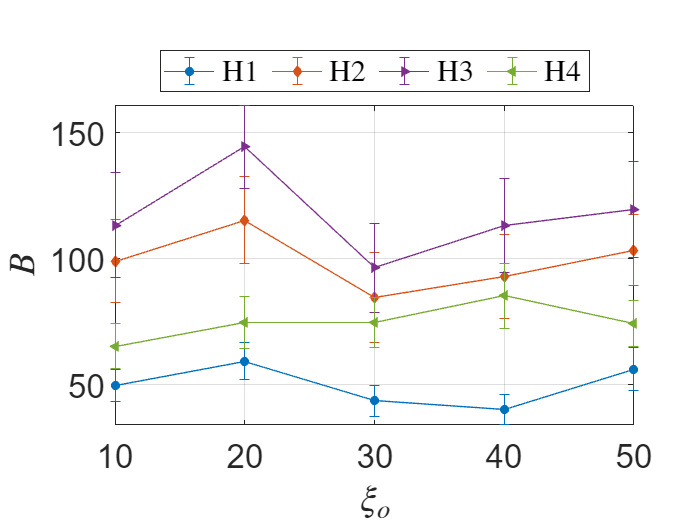

errorbar(r, B(1, :), BM(1, :), '-o', 'MarkerSize',5, 'MarkerFaceColor', "#0072BD", 'MarkerEdgeColor', "#0072BD", 'Color', "#0072BD"), hold on, grid on % 1/e
errorbar(r, B(2, :), BM(2, :), '-d', 'MarkerSize',5, 'MarkerFaceColor', "#D95319", 'MarkerEdgeColor', "#D95319", 'Color',"#D95319") 
errorbar(r, B(3, :), BM(3, :), '->', 'MarkerSize',5, 'MarkerFaceColor', "#7E2F8E", 'MarkerEdgeColor', "#7E2F8E", 'Color',"#7E2F8E") 
errorbar(r, B(4, :), BM(4, :), '-<', 'MarkerSize',5, 'MarkerFaceColor', "#77AC30", 'MarkerEdgeColor', "#77AC30",'Color',"#77AC30")
% errorbar(r, B(5, :), BM(5,:), 'v', 'MarkerSize',5, 'MarkerFaceColor', "#A2142F", 'MarkerEdgeColor', "#A2142F")
ylabel('$$B$$', 'FontSize', 22, 'Interpreter','latex')
xlabel('$$\xi_o$$', 'FontSize', 22, 'Interpreter','latex')
% legend('A1', 'A2', ...
%     'A3', 'A4','A5', "Location", 'best', 'Interpreter','latex', 'Orientation','horizontal')
% ylim([0,0.2])
legend('H1', 'H2', ...
    'H3', 'H4', "Location", 'northoutside', 'Interpreter','latex', 'Orientation','horizontal')
set(gca, 'FontSize', 20), hold off
saveas(gcf, 'BHurst.png')

% IW
%Generate Profiles
warning('off')
mu = 0;
w = 1;           %Root mean square or Interface width
alpha = 0.5;     %Roughness exponent
%P = 6000;        %Number of points
% L = 1500; 
% xi = 10;
% P = 1*L;
% N = 100;       
% delta = L/P;   

% stepSize = 100;

BM = NaN(19, 10);
BMad = BM;
E=BM;

BRef = NaN(10,1);
BMadRef = BRef;
CL = NaN(500, 100);

i = 1;
for xiRef_ = 10 : 10 : 50
    L = xiRef_*150;
    initialLength = xiRef_*10;
    stepSize = xiRef_*10;
    P = 1*L;
    N = 50;       
    delta = L/P; 

    for j = 0 : (100/N - 1)
        [xi_, Profiles_] = generateRandomCorrelatedP(alpha, xiRef_, w, mu, P, L, N, 'exp', 'InterfaceWidth');

        [x_, H_, sigma_] = GrowingWindow(delta, 0, Profiles_, ...
            stepSize, initialLength, 0, 'InterfaceWidth');

        [~, o_, ~] = GrowingWindow(delta, 0, Profiles_, ...
            stepSize, initialLength, 0, 'InterfaceWidthValue');

        dH = size(H_);
        H = nan(dH);

        for ii = 1:dH(2)
            for jj = 1:dH(3)
                H(:, ii, jj) = H_(:, ii, jj)./o_(ii, jj); % in case of IW function
            end
        end

        % [~, CL_Local] = correlationLength(1, H, 1, 'crossover');
        % [~, CL_Local] = correlationLength(1, H, 1, 'scaleKink');
        
        % [~, CL_Local] = correlationLength(1, H, 1, 'practicalRange');
        [~, CL_Local] = correlationLength(1, H, 1, 'inversedExp');

        CL_Local_size = size(CL_Local);
        CL(1:CL_Local_size(1), (j*N)+1:(j+1)*N) = CL_Local;
    end
    CLs = size(x_);

    CL = CL(1:CLs(1),:);

    BM(1:CLs(1), i) = median(x_./CL, 2, 'omitnan');
    BMad(1:CLs(1), i) = mad(x_./CL, 1, 2);

    % Change here
    xiRef = xi_(4);
    E(1:CLs(1), i) = abs(median(CL,2,'omitnan') - xiRef)/xiRef;

    pos = precisePosition(0.1, 1, E(1:CLs(1), i), 'False') + 1

    if isnan(pos)
        i = i + 1;
        continue
    end

    EInterpolation = linspace(round(pos), round(pos+1), 100);
    EPart = round(pos):round(pos+1);

    BInterpolation = interp1(EPart, BM(round(pos):round(pos+1),i), EInterpolation);
    DevInterpolation = interp1(EPart, BMad(round(pos):round(pos+1),i), EInterpolation);

    p = round(100*(pos-fix(pos)));

    if p == 0
        BRef(i) = BM(pos);
        BMadRef(i) = BMad(pos);
        i = i + 1;
        continue
    end

    BRef(i) = BInterpolation(p);
    BMadRef(i) = DevInterpolation(p);


    i = i + 1;
end

pos = 10.7900

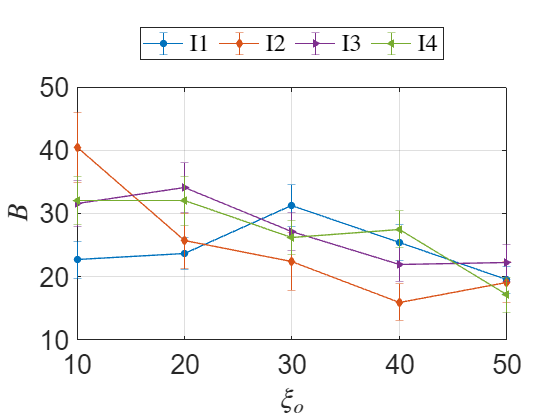

errorbar(r, B(1, :), BM(1, :), '-o', 'MarkerSize',5, 'MarkerFaceColor', "#0072BD", 'MarkerEdgeColor', "#0072BD", 'Color', "#0072BD"), hold on, grid on % 1/e
errorbar(r, B(2, :), BM(2, :), '-d', 'MarkerSize',5, 'MarkerFaceColor', "#D95319", 'MarkerEdgeColor', "#D95319", 'Color',"#D95319") 
errorbar(r, B(3, :), BM(3, :), '->', 'MarkerSize',5, 'MarkerFaceColor', "#7E2F8E", 'MarkerEdgeColor', "#7E2F8E", 'Color',"#7E2F8E") 
errorbar(r, B(4, :), BM(4, :), '-<', 'MarkerSize',5, 'MarkerFaceColor', "#77AC30", 'MarkerEdgeColor', "#77AC30",'Color',"#77AC30")
% errorbar(r, B(5, :), BM(5,:), 'v', 'MarkerSize',5, 'MarkerFaceColor', "#A2142F", 'MarkerEdgeColor', "#A2142F")
ylabel('$$B$$', 'FontSize', 22, 'Interpreter','latex')
xlabel('$$\xi_o$$', 'FontSize', 22, 'Interpreter','latex')
% ylim([0,0.2])
legend('I1', 'I2', ...
    'I3', 'I4', "Location", 'northoutside', 'Interpreter','latex', 'Orientation','horizontal')
set(gca, 'FontSize', 20), hold off
saveas(gcf, 'BIW.png')

% MD
%Generate Profiles
warning('off')
mu = 0;
w = 1;           %Root mean square or Interface width
alpha = 0.5;     %Roughness exponent

BM = NaN(19, 10);
BMad = BM;
E=BM;

BRef = NaN(10,1);
BMadRef = BRef; 
CL = NaN(500, 100);

i = 1;
for xiRef_ = 10:10:50
    L = xiRef_*1100;
    initialLength = xiRef_*200;
    stepSize = xiRef_*100;
    P = 1*L;
    N = 50;       
    delta = L/P; 

    for j = 0 : (100/N - 1)
        [xi_, Profiles_] = generateRandomCorrelatedP(alpha, xiRef_, w, mu, P, L, N, 'exp', 'maxDifference');

        [x_, H_, sigma_] = GrowingWindow(delta, 0, Profiles_, ...
            stepSize, initialLength, 0, 'maxDifference');

        [~, o_, ~] = GrowingWindow(delta, 0, Profiles_, ...
            stepSize, initialLength, 0, 'RangeValue');

        dH = size(H_);
        H = nan(dH);

        for ii = 1:dH(2)
            for jj = 1:dH(3)
                H(:, ii, jj) = 4*H_(:, ii, jj)./o_(ii, jj);
            end
        end

        % [~, CL_Local] = correlationLength(1, H, 1, 'crossover');
        [~, CL_Local] = correlationLength(1, H, 1, 'scaleKink');

        CL_Local_size = size(CL_Local);
        CL(1:CL_Local_size(1), (j*N)+1:(j+1)*N) = CL_Local;
    end
    CLs = size(x_);

    CL = CL(1:CLs(1),:);

    BM(1:CLs(1), i) = median(x_./CL, 2, 'omitnan');
    BMad(1:CLs(1), i) = mad(x_./CL, 1, 2);

    % Change here
    xiRef = xi_(2);
    E(1:CLs(1), i) = abs(median(CL,2,'omitnan') - xiRef)/xiRef;

    pos = precisePosition(0.1, 1, E(1:CLs(1), i), 'False') + 1

    if isnan(pos)
        i = i + 1;
        continue
    end

    EInterpolation = linspace(round(pos), round(pos+1), 100);
    EPart = round(pos):round(pos+1);

    BInterpolation = interp1(EPart, BM(round(pos):round(pos+1),i), EInterpolation);
    DevInterpolation = interp1(EPart, BMad(round(pos):round(pos+1),i), EInterpolation);

    p = round(100*(pos-fix(pos)));

    if p == 0
        BRef(i) = BM(pos);
        BMadRef(i) = BMad(pos);
        i = i + 1;
        continue
    end

    BRef(i) = BInterpolation(p);
    BMadRef(i) = DevInterpolation(p);


    i = i + 1;
end

pos = 7.4700

pos = 4.7300

pos = 2.2900

pos = 1.9700

pos = 1.4600

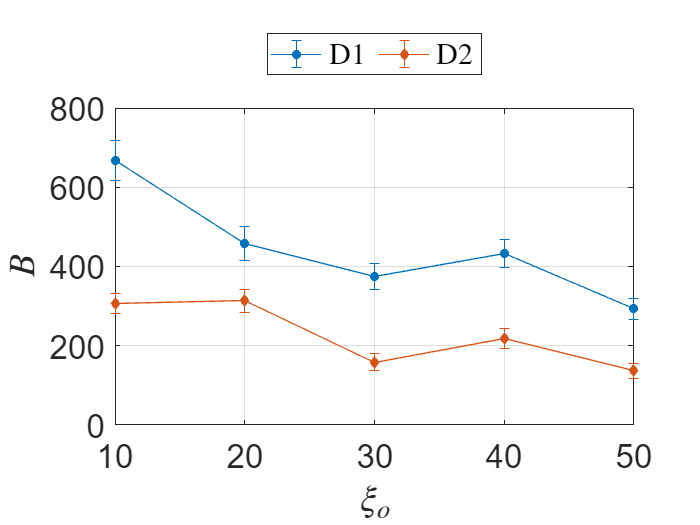

errorbar(r, B(1, :), BM(1, :), '-o', 'MarkerSize',5, 'MarkerFaceColor', "#0072BD", 'MarkerEdgeColor', "#0072BD", 'Color', "#0072BD"), hold on, grid on % 1/e
errorbar(r, B(2, :), BM(2, :), '-d', 'MarkerSize',5, 'MarkerFaceColor', "#D95319", 'MarkerEdgeColor', "#D95319", 'Color',"#D95319") 
ylabel('$$B$$', 'FontSize', 22, 'Interpreter','latex')
xlabel('$$\xi_o$$', 'FontSize', 22, 'Interpreter','latex')
% ylim([0,0.2])
legend('D1', 'D2', "Location", 'northoutside', 'Interpreter','latex', 'Orientation','horizontal')
set(gca, 'FontSize', 20), hold off
saveas(gcf, 'BD.png')

function A_ = errorBoundariesA(sigma, A)
dA = size(A);

if length(dA) == 3
    for c = 1 : dA(3)
        for b = 1 : dA(2)
            position = find(A(:, b, c) <= sigma(:, b, c), 1, 'first');
            A(position : end, b,  c) = nan;
        end
    end
elseif length(dA) == 2
    for b = 1 : dA(2)
        position = find(A(:, b) <= sigma(:, b), 1, 'first');
        A(position : end, b) = nan;
    end
end
A_ = A;
end

function s = std_mean(var_)
dx = size(var_);
s = sqrt(sum((var_ - mean(var_, 2, 'omitnan')).^2, 2, 'omitnan'))/dx(2);
end

function s = full_error(mean, system)

end

%%%%%%%%%%%%%%%%%%
function [xPosition_, CFC_, sigmaC_] = GrowingWindow(delta, SystematicError, Profiles, ...
    stepSize, initialLength, endLength, Method)
% ==============================================================
%This method analyses profiles on the sabsequent increasing lengthscale.
% Each profile is consecutivly taken on the lengthscale (0, l), where l is
% changing as l = l + n*stepSize, where n is the number of iteration. On the
% first iteration, profiles are analysed on the l = initialLength.
% ==============================================================
%INPUT:
%
%delta is the difference between two points of the profile, [L]. For
% example: delta = x(2) - x(1).
%
%SystematicError is the error of measurements (погрешность
% измерения), [L].
%
%Profiles is a matrix which contains all studying profiles, [L].
% The matrix has a size (n, m), n, m > 1. Each profile
% should be written along a column. Therefore, the column's number
% is equal to the profile number. For example, there are ten profiles of
% length 1000. Thus, the matrix Profiles is of the size (1000, 10). If you
% would like to call the first profile the code should be as Profiles(:, 1),
% the fifth is Profiles(:, 5), etc.
%
%stepSize is the difference between two studying lengthscales of the stufying profile, [L].
% For instance, on the n-th iteration, the profile of the length l_n is analysed.
% On the next iteration, the profile of the length l_n + stepSize will be
% analysed. Thus, the step size is defined as the difference between
% profile's lengthscales on two following iterations, stepSize = (l_n + stepSize) - l_n.
% Note: l_0 <= l_n <= L, where L is the
% full profile length or the profile length at the last iteration, and l_0 is the
% initial profile length.
%
%initialLength is the lengthscale on which a profile is analysed on the
% first iteration, [L].
%
%Method contains information about the correlation method. It might be:
% Hurst, maxDifference, Autocorrelation, Autocovariance methods, and
% InterfaceWidth.
%
%OUTPUT:
%
%xPosition_ is the lengthscale on which profiles were analysed, [L]. It
% contains all l_n's. This variable is usually used to plot the value of
% the correlation length and roughness exponent.
%
%CFC_ contains all correlation functions of analysed profiles, [L^2] for
% Autocovariance mathod, and [L] for Autocorrelation, Hurst, and
% maxDifference methods. Exception, if the InterfaceWidth has been called
% then it returns values of the root mean square with the following
% dimension [L]. CFC_ is a (n, m, k) matrix where n, m, and k > 1. In
% the n's values of the correlation function are written, when k is a
% profile's number. The m's correspond the profile analysed on the n's lenthscale.
% If you would like to get a correlation function for a
% 10's profile analysed on the initial length then it would be that CFC_(:, 1, 10),
% for a 25's profile it would be CFC_(:, 1, 25), etc. If you would like to
% get a correlation function analysed on the n'th lenthscale then it would
% be CFC_(:, n, 10), CFC_(:, n, 25), etc.
%
%sigmaC_ is a standard error (стандартное отклонение или стандартная ошибка, погрешность вычислений), [L].
%
% ==============================================================

arguments
    delta (1,1) double
    SystematicError (1,1) double
    Profiles (:, :) double
    stepSize (1,1) double
    initialLength (1,1) double
    endLength (1,1) double
    Method (1,:) char {mustBeMember(Method,{'Hurst', 'Autocorrelation', ...
        'Autocovariance', 'maxDifference', 'InterfaceWidth', 'HurstNormalised', ...
        'InterfaceWidthValue', 'RangeValue'})} = 'Autocorrelation'
end

%Redefine stepSize and initialLength in number of points
stepSize = round(stepSize/delta, 0);
initialLength = round(initialLength/delta, 0);
endLength = round(endLength/delta, 0);

%Set-up default values
if endLength <= 0
    endLength = profileLength(delta, Profiles, 'max')/delta;
end

dProfiles = size(Profiles);

%Initialize containers
% CFC_ = NaN(round(dProfiles(1)/4), round((endLength - initialLength)/stepSize), dProfiles(2));
% sigmaC_ = CFC_;

%dCFC_ = size(CFC_)
CFC_ = NaN(dProfiles(1), round(dProfiles(1)/stepSize), dProfiles(2));
sigmaC_ = NaN(dProfiles(1), round(dProfiles(1)/stepSize), dProfiles(2));

for profileNumber = 1 : dProfiles(2)

    profileLengthNumber = 1;

    profile = Profiles(:, profileNumber);
    profile(isnan(profile)) = [];
    dprofile = size(profile);

    for endPoint = initialLength : stepSize : dprofile(1)

        profilePartial = profile(1 : endPoint);
        %subtract the linear trend and mean height
        profilePartial = subtractLinearTrendAndMeanHeight(delta, profilePartial);

        %profileLength = endPoint*delta

        if endPoint > endLength
            %profileLength = endPoint*delta
            %disp('The profile length is larger than the boundary.')
            break
        end


        if strcmp(Method, 'Hurst')
            [CF, sigma] = Hurst(SystematicError, profilePartial);
        elseif strcmp(Method, 'Autocorrelation')
            [CF, sigma] = Autocorrelation(SystematicError, profilePartial);
        elseif strcmp(Method, 'maxDifference')
            [CF, sigma] = MD(SystematicError, profilePartial);
        elseif strcmp(Method, 'InterfaceWidth')
            [CF, sigma] = IWFunction(SystematicError, profilePartial);
        elseif strcmp(Method, 'InterfaceWidthValue')
            [CF, sigma] = InterfaceWidth(SystematicError, profilePartial);
        elseif strcmp(Method, 'RangeValue')
            CF = range(profilePartial);
            sigma = nan;
        end

        dCF = size(CF);

        CFC_(1 : dCF(1), profileLengthNumber, profileNumber) = CF;
        sigmaC_(1 : dCF(1), profileLengthNumber, profileNumber) = sigma;

        xPosition_(profileLengthNumber, 1) = delta*endPoint;
        profileLengthNumber = profileLengthNumber + 1;
    end
end
%sigmaC_ = 1;
if strcmp(Method, 'InterfaceWidthValue') || strcmp(Method, 'RangeValue')
    [CFC_, sigmaC_] = reshapeIW(CFC_, sigmaC_);
end
end


function [x_, CFC_, sigmaC_] = FullWindow(delta, SystematicError, Profiles, Method)
% ==============================================================
%This method analyses profiles on the given lengthscale, i.e. if the length
%of a profile is 100 then the full length would be taken, and a correlation
%function would be found on its length.
% ==============================================================
%INPUT:
%
%delta is the difference between two points of the profile, [L]. For
% example: delta = x(2) - x(1).
%
%SystematicError is the error of measurements (погрешность
% измерения), [L].
%
%Profiles is a matrix which contains all studying profiles, [L].
% The matrix has a size (n, m), n, m > 1. Each profile
% should be written along a column. Therefore, the column's number
% is equal to the profile number. For example, there are ten profiles of
% length 1000. Thus, the matrix Profiles is of the size (1000, 10). If you
% would like to call the first profile the code should be as Profiles(:, 1),
% the fifth is Profiles(:, 5), etc.
%
%Method contains information about the correlation method. It might be:
% Hurst, maxDifference, Autocorrelation, Autocovariance methods, and
% InterfaceWidth.
%
%OUTPUT:
%
%x_ is the lengthscale on which profiles were analysed, [L].
%
%CFC_ contains all correlation functions of analysed profiles, [L^2] for
% Autocovariance mathod, and [L] for Autocorrelation, Hurst, and
% maxDifference methods. Exception, if the InterfaceWidth has been called
% then it returns values of the root mean square with the following
% dimension [L]. CFC_ is a (n, m, k) matrix where n, k > 1 and m = 1. In
% the n's values of the correlation function are written, when k is a
% profile's number. If you would like to get a correlation function for a
% 10's profile then it would be that CFC_(:, 1, 10), for a 25's profile
% would be CFC_(:, 1, 25), etc.
%
%sigmaC_ is a standard error (стандартное отклонение или стандартная ошибка, погрешность вычислений), [L].
%
% ==============================================================

arguments
    delta (1,1) double
    SystematicError (1,1) double
    Profiles (:, :) double
    Method (1,:) char {mustBeMember(Method,{'Hurst', 'Autocorrelation', ...
        'Autocovariance', 'maxDifference', 'InterfaceWidth', 'HurstNormalised', ...
        'InterfaceWidthValue', 'RangeValue'})} = 'Hurst'
end

dProfiles = size(Profiles);

%Initialize main variables
CFC_ = NaN(dProfiles(1)/4, 1, dProfiles(2));
sigmaC_ = CFC_;
% CFC_ = NaN(dProfiles(1), 1, dProfiles(2));
% sigmaC_ = NaN(dProfiles(1), 1, dProfiles(2));

for profileNumber = 1 : dProfiles(2)

    profile = Profiles( : , profileNumber);
    profile(isnan(profile)) = [];

    profile = subtractLinearTrendAndMeanHeight(delta, profile);


    if strcmp(Method, 'Hurst')
        [CF, sigma] = Hurst(SystematicError, profile);
    elseif strcmp(Method, 'Autocorrelation')
        [CF, sigma] = Autocorrelation(SystematicError, profile);
    elseif strcmp(Method, 'maxDifference')
        [CF, sigma] = MD(SystematicError, profile);
    elseif strcmp(Method, 'InterfaceWidthValue')
        %Note: It returns RMS or interface width in the CF matrix
        [CF, sigma] = InterfaceWidth(SystematicError, profile);
    elseif strcmp(Method, 'InterfaceWidth')
        [CF, sigma] = IWFunction(SystematicError, profile);
    elseif strcmp(Method, 'RangeValue')
        CF = range(profile);
        sigma = nan;
    end

    dCF = size(CF);

    CFC_(1 : dCF(1), 1, profileNumber) = CF;
    sigmaC_(1 : dCF(1), 1, profileNumber) = sigma;
end

length = max(sum(~isnan(CFC_)));
x_ = delta.*linspace(0, length - 1, length)';

if strcmp(Method, 'InterfaceWidthValue') || strcmp(Method, 'RangeValue')
    [CFC_, sigmaC_] = reshapeIW(CFC_, sigmaC_);
end
end


function [CF_, sigma_] = Hurst(SystematicError, profile)
% ==============================================================
%This method calculates
% ==============================================================
%INPUT:
%
%
%OUTPUT:
%
%
% ==============================================================

arguments
    SystematicError (1, 1) double
    profile (:, 1) double
end

dprofile = size(profile);

%Initialise containers
CF_ = nan(2, 1);
sigma_ = CF_;
% profile = profile - mean(profile);

for k = 0 : dprofile(1) - 1

    profileShifted = circshift(profile, - k);
    profileShifted(dprofile(1) - (k - 1) : end) = nan;
    profileDifference = profileShifted - profile;
    CF_(k + 1) = sqrt(sum((profileDifference).^2, 'omitnan')/(dprofile(1) - k));
    sigma_(k + 1) = nan;
end
end


function [CFAutocorrelation_, sigmaAutocorrelation_] = Autocorrelation(SystematicError, profile)
% ==============================================================
%This method calculates the autocorrelation function and the calculation error.
% ==============================================================
%INPUT:
%
%SystematicError is the error of measurements (погрешность измерений), [L].
%
%profile is the studying profile i.e. h = f(x), [L].
%
%OUTPUT:
%
%CFAutocorrelation_ returns the correlation function of the profile, [L].
%
%sigmaAutocorrelation_ returns the error of calculations (стандартное отклонение
% или стандартная ошибка, погрешность вычислений), [L].
% ==============================================================
%Note: There is the in-built matlab function autocorr(y) in the
% Econometrics toolbox.
% ==============================================================


arguments
    SystematicError (1, 1) double
    profile (:, 1) double
end
profile = profile - mean(profile);

[interfaceWidth, ~] = InterfaceWidth(SystematicError, profile);
% interfaceWidth = std(profile);

%Estimate profile's size
dprofile = size(profile);

%Initialise containers
CFAutocorrelation_ = nan(2, 1);
sigmaAutocorrelation_ = CFAutocorrelation_;
i = 0;
%Start the iteration loop
for r = 0 : dprofile(1) - 1

    profileShifted = circshift(profile, -r);                %Shift a profile on r
    profileShifted(dprofile(1) - (r - 1) : end) = nan;      %Put nan's to rows which are not overlapped with the unshifted profile

    CFAutocorrelation_(r + 1) = (sum(profile.*profileShifted, 'omitnan')/(dprofile(1) - r))/interfaceWidth^2;
    sigmaAutocorrelation_(r + 1) = largeLagStandardError(dprofile(1), CFAutocorrelation_);

        if CFAutocorrelation_(r + 1) <= 0
            break
            % i = i + 1;
            % %If the autocovariance function is less than null then stop
            % % calculations and go out of the cycle
            % if i > 1 %150
            %     break
            % end
        end
end
CFAutocorrelation_(1) = 1;
end


function sigma_ = largeLagStandardError(numberOfPoints, CFAutocorrelation_)
sigma_ = sqrt((1/numberOfPoints)*(2*sum(CFAutocorrelation_.^2) - 1));
% sigma_ = sqrt((1/numberOfPoints)*(1 + 2*sum(CFAutocorrelation_(2 : end))));
end

function [interfaceWidth_, sigmaInterfaceWidth_] = InterfaceWidth(SystematicError, profile)
% ==============================================================
%This method calculates the root mean square of the profile and the calculation
%error.
% ==============================================================
%INPUT:
%
%SystematicError is the error of measurements (погрешность измерений), [L].
%
%profile is the studying profile i.e. h = f(x), [L].
%
%OUTPUT:
%
%interfaceWidth_ returns the value of root mean square, [L].
%
%sigmaInterfaceWidth_ returns the error of calculations (стандартное отклонение
% или стандартная ошибка, погрешность вычислений), [L].
% ==============================================================

arguments
    SystematicError (1, 1) double
    profile (:, 1) double
end

%interfaceWidth_ = rms(profile, 'omitnan');                    %The in-built matlab function
dProfile = size(profile);
% profile = profile - mean(profile);
interfaceWidth_i = profile.^2;

interfaceWidth_ = sqrt(1/dProfile(1)*sum(interfaceWidth_i, 'omitnan'));

sigmaInterfaceWidth_ = nan;
end


%%%%%%%%%%%%%%%%%%%%%%%%%%% Correlation Length %%%%%%%%%%%%%%%%%%%%%%%
function [alpha_, CL_] = correlationLengthAvr(delta, CF, saturatedValue, Method)
arguments
    delta (1, 1) double
    CF (:, :) double
    saturatedValue (1, 1) double
    Method (1,:) char {mustBeMember(Method,{'crossover', 'firstZeroPoint', ...
        'powerLawFirstZeroPoint', '1/e', 'expFirstZeroPoint', ...
        'scaleKink', 'inversedExp', 'practicalRange', '1/eExp'})} = '1/e'
end

dCF = size(CF);
CL_ = nan(1, dCF(2));
alpha_ = CL_;

for profileNumber = 1 : dCF(2)
    if strcmp(Method, 'crossover') || strcmp(Method, 'scaleKink')
        [alpha_(1, profileNumber), CL_(1, profileNumber)] = crossover(delta, CF(:, profileNumber), saturatedValue, Method);
    elseif strcmp(Method, 'inversedExp')
        CL_(1, profileNumber) = inversedExp(delta, saturatedValue, CF(:, profileNumber));
    elseif strcmp(Method, 'practicalRange')
        CL_(1, profileNumber) = practicalRange(delta, saturatedValue, CF(:, profileNumber));
    elseif strcmp(Method, '1/e')
        CL_(1, profileNumber) = firstZeroPoint(delta, CF(:, profileNumber), '1/e');
    elseif strcmp(Method, 'firstZeroPoint')
        CL_(1, profileNumber) = firstZeroPoint(delta, CF(:, profileNumber));
    elseif strcmp(Method, 'expFirstZeroPoint')
        CL_(1, profileNumber) = firstZeroPoint(delta, CF(:, profileNumber), '0.01', 'exp');
    elseif strcmp(Method, 'powerLawFirstZeroPoint')
        CL_(1, profileNumber) = firstZeroPoint(delta, CF(:, profileNumber), '0.01', 'power');
    elseif strcmp(Method, '1/eExp')
        CL_(1, profileNumber) = firstZeroPoint(delta, CF(:, profileNumber), '1/e', 'exp');
    end
end
end


function [alpha_, CL_] = correlationLength(delta, CF, saturatedValue, Method)
arguments
    delta (1, 1) double
    CF (:, :, :) double
    saturatedValue (1, 1) double
    Method (1,:) char {mustBeMember(Method,{'crossover', 'firstZeroPoint', ...
        'powerLawFirstZeroPoint', '1/e', 'expFirstZeroPoint', ...
        'scaleKink', 'inversedExp', 'practicalRange', '1/eExp'})} = '1/e'
end

dCF = size(CF);
CL_ = nan(dCF(2),dCF(3));
alpha_ = CL_;

for profileNumber = 1 : dCF(3)
    CFMain = CF( : , : , profileNumber);
    CFMain = reshape(CFMain, [dCF(1), dCF(2)]);
    dCFMain = size(CFMain);

    for profile_length = 1 : dCFMain(2)

        CFOne = CFMain( : , profile_length);
        CFOne(isnan(CFOne)) = [];
        dCFOne = size(CFOne);

        if dCFOne(1) > 3
            if strcmp(Method, 'crossover') || strcmp(Method, 'scaleKink')
                [alpha_(profile_length, profileNumber), CL_(profile_length, profileNumber)] = crossover(delta, CFOne, saturatedValue, Method);
            elseif strcmp(Method, 'inversedExp')
                CL_(profile_length, profileNumber) = inversedExp(delta, saturatedValue, CFOne);
            elseif strcmp(Method, 'practicalRange')
                CL_(profile_length, profileNumber) = practicalRange(delta, saturatedValue, CFOne);
            elseif strcmp(Method, '1/e')
                CL_(profile_length, profileNumber) = firstZeroPoint(delta, CFOne, '1/e');
            elseif strcmp(Method, 'firstZeroPoint')
                CL_(profile_length, profileNumber) = firstZeroPoint(delta, CFOne);
            elseif strcmp(Method, 'expFirstZeroPoint')
                CL_(profile_length, profileNumber) = firstZeroPoint(delta, CFOne, '0.01', 'exp');
            elseif strcmp(Method, 'powerLawFirstZeroPoint')
                CL_(profile_length, profileNumber) = firstZeroPoint(delta, CFOne, '0.01', 'power');
            elseif strcmp(Method, '1/eExp')
                CL_(profile_length, profileNumber) = firstZeroPoint(delta, CFOne, '1/e', 'exp');
            end
        end
    end
end
end

function CL_ = firstZeroPoint(delta, CF, Method, Method2)
% ==============================================================
%INPUT:
%
%delta is the difference between two points of the profile, [L].
%
%CF is the correlation function found with the autocovariance or
%autocorrelation functions, [L^2].
%
%OUTPUT: CL_ returns the value of the correlation length, [L].
% ==============================================================

arguments
    delta (1, 1) double
    CF (:, 1) double
    Method (1,:) char {mustBeMember(Method,{'0.01', '0.1', '1/e'})} = '0.01'
    Method2 (1,:) char {mustBeMember(Method2,{'exp', 'power', 'nan'})} = 'nan'
end
%Choose point of intersection
% zeroPoint = str2double(Method);
if strcmp(Method, '1/e')
    zeroPoint = 1/exp(1);
else
    zeroPoint = str2double(Method);
end
%%%%%%%%%5
if strcmp(Method2, 'exp') || strcmp(Method2, 'power')
    [x, CF] = cutCFandGenX(delta, CF);

    if strcmp(Method2, 'exp')
        f = fit(x, CF, 'exp1');
    elseif strcmp(Method2, 'power')
        x(1) = 0.01*x(2);
%         f = fit(x, CF, 'power2');
        ft = fittype('-a*x^0.5 + 1', 'dependent', 'y', 'independent', 'x', 'coefficients', 'a');
        f = fit(x, CF, ft, 'StartPoint', 0.4);
    end
    dCF = size(CF);
    coeff = 10;
    x = delta*linspace(0, coeff*(dCF(1) - 1), coeff*dCF(1));
    
    CFInterpolated = f(x);
    
    zeroPosition = find(CFInterpolated <= 0, 1, 'first');
    CFInterpolated(zeroPosition + 1 : end) = nan;
    CFInterpolated(isnan(CFInterpolated)) = [];

    CF = CFInterpolated;
end


CL_ = precisePosition(zeroPoint, delta, CF, 'False');
end

function CL_ = precisePosition(zeroPoint, delta, CF, less)
% Interpolate position
if ~isempty(zeroPoint)
    position = find(CF == zeroPoint, 1, 'first');
    if position > 1
        CL_ = delta*(position - 1);
    else
        if strcmp(less, 'True')
            position = find(CF > zeroPoint, 1, 'first');
            if position > 1
                CFPart = CF(position - 1 : position);
                xPart = delta*linspace(position - 2, position - 1, 2)';
                xInterpolation = delta*linspace(position - 2, position - 1, 100)';
                CFInterpolation = interp1(xPart, CFPart, xInterpolation);
                positionInterpolation = find(CFInterpolation <= zeroPoint, 1, 'last');
                CL_ = delta*((position - 1) - (1 - positionInterpolation/100));
            else
                position = nan;
                CL_ = delta*position;
            end
        else
            position = find(CF < zeroPoint, 1, 'first');
        
            if position > 1
                CFPart = CF(position - 1 : position);
                xPart = delta*linspace(position - 2, position - 1, 2)';
                xInterpolation = delta*linspace(position - 2, position - 1, 100)';
                CFInterpolation = interp1(xPart, CFPart, xInterpolation);
                positionInterpolation = find(CFInterpolation <= zeroPoint, 1, 'first');
                CL_ = delta*((position - 1) - (1 - positionInterpolation/100));
            else
                position = nan;
                CL_ = delta*position;
            end
        end
    end
else
    CL_ = nan;
end
end

%%%%%%%%%%%%%%%%%%%%%% Hurst %%%%%%%%%%%%%%%%%%%%%%%%
function CL_ = practicalRange(delta, saturatedValue, CF)
arguments
    delta (1, 1) double
    saturatedValue (1, 1) double
    CF (:, 1) double
end
[~, CF] = cutCFandGenX(delta, CF);
CL_ = precisePosition(0.95*saturatedValue, delta, CF, 'True');
end


function [alpha_, CL_] = crossover(delta, CF, saturatedValue, Method)
% Correlation function, CF, should be normalized
arguments
    delta (1, 1) double
    CF (:, 1) double
    saturatedValue (1, 1) double
    Method (1,:) char {mustBeMember(Method,{'crossover', 'scaleKink'})} = 'crossover'
end

if strcmp(Method, 'scaleKink')
    [xOrig, CFOrig] = cutCFandGenX(delta, CF);
    xOrig(1) = [];
    CFOrig(1) = [];
end

CF = cutAtPoint(.7944, CF, 'False'); %In case of Hurst function


[x, CF] = cutCFandGenX(delta, CF);
coef = [nan;0.5];

if length(CF) <= 3
    CL_ = nan;
    alpha_ = nan;
    return
end

dCF = size(CF);
% x(1) = 0.001;
x(1) = [];
CF(1) = [];

ft = fittype('a*x^0.5', 'dependent', 'y', 'independent', 'x', 'coefficients', 'a');
expFit = fit(x, CF, ft, 'StartPoint', 0.4);

coef(1) = coeffvalues(expFit);

if strcmp(Method, 'crossover')
    boundary = saturatedValue;
    CL_ = (1/coef(1)).^(1/coef(2));
    alpha_ = coef(2);
else
    CFApprox = coef(1).*xOrig.^(coef(2));
    position = find(CFApprox <= CFOrig, 1, 'last');
    % xOrig
    xq = delta*linspace(position, position+1, 100)';
    CFq = interp1(xOrig, CFOrig, xq);

    CFApprox = coef(1).*xq.^(coef(2));
    % plot(CFApprox), hold on, grid on,
    % plot(CFq), hold off

    position100 = find(CFApprox <= CFq, 1, 'last');
    CL_= delta*(position + position100/100);
    % boundary = CFOrig(position+1);
    
    % x = delta*linspace(0, 10*dCF(1), 10*dCF(1))';
    % CFApprox = coef(1).*x.^(coef(2));
    % 
    % CL_ = precisePosition(boundary, delta, CFApprox, 'True');
    alpha_ = coef(2);
end
% x = delta*linspace(0, 10*dCF(1), 10*dCF(1))';
% CFApprox = coef(1).*x.^(coef(2));
% CL_ = precisePosition(boundary, delta, CFApprox, 'True');
% alpha_ = coef(2);
end

function CL_ = inversedExp(delta, saturatedValue, CF)
% Works with nornalised IW and Hurst
arguments
    delta (1, 1) double
    saturatedValue (1, 1) double
    CF (:, 1) double
end
% CF = cutAtPoint(2/3*0.7944, CF, 'False');
CF = cutAtPoint(0.7944, CF, 'False');
[x, CF] = cutCFandGenX(delta, CF./saturatedValue);
if length(CF) > 5
    ft = fittype('sqrt(1 - exp(-x/xi))', 'dependent', 'y', 'independent', 'x', 'coefficients', 'xi');
    expFit = fit(x, CF, ft, 'StartPoint', 10);

    %coeffs = coeffvalues(expFit);
    CL_ = coeffvalues(expFit);
else
    CL_ = nan;
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Profile Generator %%%%%%%%%%%%%%%%%%%%%%%%%%%
function [xi_, Profiles_] = generateRandomCorrelatedP(alpha, xi, IW, mean, numberOfPoints, ...
    Length, numberOfProfiles, Method, Method2)
% ==============================================================
%INPUT:
%
%alpha is the roughness exponent, [-]. 0 < alpha < 1.
%
%xi is the lateral correlation length, [L].
%
%IW is the interface width or root mean square. It is also sigma
% in the normal distribution, [L].
%
%mean is a mean value of the profile. It is also mu in the normal
% distribution, [L].
%
%numberOfPoints is the number of generated points, [-].
%
%Length is the profile length, [L].
%
%numberOfProfiles is the number of profiles to be generated, [-].
%
%OUTPUT:
%
%Profiles_ returns correlated random profile with the given correlation
% length xi, interface width (RMS) IW, and roughness exponent (alpha).
% numberOfProfiles profiles would be generated on the length Length = (0, Length)
% on the numberOfPoints points.
% ==============================================================

arguments
    alpha (1, 1) double
    xi (1, 1) double
    IW (1, 1) double
    mean (1, 1) double
    numberOfPoints (1, 1) double
    Length (1, 1) double
    numberOfProfiles (1, 1) double
    Method (1,:) char {mustBeMember(Method,{'exp', 'K'})} = 'exp'
    Method2 (1,:) char {mustBeMember(Method2,{'Hurst', 'Autocorrelation', ...
        'Autocovariance', 'maxDifference', 'InterfaceWidth', 'HurstNormalised', ...
        'InterfaceWidthValue'})} = 'Autocorrelation'
end

r = linspace(0, Length, numberOfPoints)';

if strcmp(Method, 'exp')
    A = exp( - (r./xi).^(2*alpha));
else
    A = (alpha/(2^(alpha - 1)*gamma(alpha + 1)))*(sqrt(2*alpha)*r./xi).^alpha.*besselk(alpha, sqrt(2*alpha)*r./xi);
    A(1) = 1;
end

%dA = size(A);
for i = 1 : length(A) %dA(1)
    if A(i) < 10^-5
        A(i + 1 : end) = 0;
        break
    end
end

C = sptoeplitz(A, A);

C = chol(C, 'lower');

r = normrnd(mean, IW, [numberOfPoints, numberOfProfiles]);

Profiles_ = C*r;
delta = Length/numberOfPoints;

if strcmp(Method2, 'Autocorrelation')
    [~, xi_(1, :)] = correlationLengthAvr(delta, A, 0, '1/e');
    [~, xi_(2, :)] = correlationLengthAvr(delta, A, 0, 'firstZeroPoint');

    ACut = cutAtPoint(0.1, A);
    [~, xi_(3, :)] = correlationLengthAvr(delta, ACut, 0, 'powerLawFirstZeroPoint');
    xi_(4, :) = xi_(2, :);
    xi_(5, :) = xi_(1, :);
elseif strcmp(Method2, 'Hurst')
    H = sqrt((1 - A));

    [~, xi_(1, :)] = correlationLengthAvr(delta, H, 1, 'crossover');
    [~, xi_(2, :)] = correlationLengthAvr(delta, H, 1, 'scaleKink');
    [~, xi_(3, :)] = correlationLengthAvr(delta, H, 1, 'practicalRange');
    [~, xi_(4, :)] = correlationLengthAvr(delta, H, 1, 'inversedExp');

elseif strcmp(Method2, 'InterfaceWidth')
    if xi == 10
        xi_ = [59.3314; 30.2617; 212.6177; 40.6141];
    elseif xi == 20
        xi_ =  [119.1362; 60.8165; 394.5128; 82.8136];
    elseif xi == 30
        xi_ = [174.9972; 90.0318; 574.5646; 122.7556];
    elseif xi == 40
        xi_ = [236.5863; 122.4825; 733.7477; 166.9224];
    elseif xi == 50
        xi_ = [286.7595; 150.2019; 885.6844;203.2688];
    end

elseif strcmp(Method2, 'maxDifference')
    if xi == 10
        xi_ = [13.8497; 25.0832];
    elseif xi == 20
        xi_ =  [22.2009; 41.2227];
    elseif xi == 30
        xi_ = [29.5739; 56.8296];
    elseif xi == 40
        xi_ = [36.9538; 69.2220];
    elseif xi == 50
        xi_ = [43.1109; 82.9980];
    end
end

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Mean Height Function %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [meanHeight_, sigmaMeanHeight_] = meanHeight(SystematicError, profile)
% ==============================================================
%This method calculates the mean height of the profile and the calculation
%error.
% ==============================================================
%INPUT:
%
%SystematicError is the error of measurements (погрешность измерений), [L].
%
%profile is the studying profile i.e. h = f(x), [L].
%
%OUTPUT:
%
%meanHeught_ returns the value of root mean square, [L].
%
%sigmaMeanHeight_ returns the error of calculations (стандартное отклонение
% или стандартная ошибка, погрешность вычислений), [L].
% ==============================================================

arguments
    SystematicError (1, 1) double
    profile (:, 1) double
end

meanHeight_ = mean(profile, 'omitnan');
sigmaMeanHeight_ = meanHeightError(meanHeight_, profile, SystematicError);
end


%Description
function sigmaMeanHeight_ = meanHeightError(meanHeight, profile, SystematicError)
dProfile = size(profile);
sigma_m = 1/dProfile(1)*sqrt(sum((meanHeight - profile).^2, 'omitnan'));
sigmaMeanHeight_ = sqrt(SystematicError^2 + sigma_m^2);
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Pre-processing Functions %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function profile_ = subtractLinearTrend(delta, profile)
% ==============================================================
%This method subtracts the linear trend from the profile.
% ==============================================================
%INPUT:
%
%delta is the distance between two points of the profile, i.e. delta = x_2 - x_1, [L].
%
%profile is the studying profile i.e. h = f(x), [L].
%
%OUTPUT:
%
%profile_ returns the without the linear trend, [L].
% ==============================================================

arguments
    delta (1, 1) double
    profile (:, 1) double
end

dprofile = size(profile);
x = delta.*linspace(0, dprofile(1), dprofile(1))';
linTrend = fit(x, profile, 'poly1');
profile_ = profile - linTrend(x);
end

function profile_ = subtractLinearTrendAndMeanHeight(delta, profile)
% ==============================================================
%This method subtracts the linear trend and mean height from the profile.
% ==============================================================
%INPUT:
%
%delta is the distance between two points of the profile, i.e. delta = x_2 - x_1, [L].
%
%profile is the studying profile i.e. h = f(x), [L].
%
%OUTPUT:
%
%profile_ returns the without the linear trend and with the zore mean height, [L].
% ==============================================================

arguments
    delta (1, 1) double
    profile (:, 1) double
end

profile = subtractLinearTrend(delta, profile);
[meanHeight_local, ~] = meanHeight(0, profile);
profile_ = profile - meanHeight_local;
end

function Length_ = profileLength(delta, Profiles, Method)

arguments
    delta (1,1) double
    Profiles
    Method (1,:) char {mustBeMember(Method,{'max', 'min'})} = 'max'
end

numberOfElements = sum(~isnan(Profiles));
Length = delta*(numberOfElements);

if strcmp(Method, 'max')
    Length_ = max(Length);
else
    Length_ = min(Length);
end

if Length_ == 0
    Length_ = round(mean(Length),0);
end
end


function [CFC_, sigmaC_] = reshapeIW(CFC, sigmaC)
CFC = CFC(1, :, :);
dCFC = size(CFC);
CFC_ = reshape(CFC, [dCFC(2), dCFC(3)]);

sigmaC = sigmaC(1, :, :);
sigmaC_ = reshape(sigmaC, [dCFC(2), dCFC(3)]);
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Supporting Functions %%%%%%%%%%%%%%%%%%%%%%
function [x_, CF_] = cutCFandGenX(delta, CF)
%Cuts nan's and generates x's
position = find(isnan(CF) == 1, 1, 'first');
CF(position : end) = [];
dCF = size(CF);
x_ = delta*linspace(0, dCF(1) - 1, dCF(1))';
CF_ = CF;
end

function CF = cutAtPoint(point, CF, Method)
arguments
    point (1, :) double
    CF (:, :) double
    Method (1,:) char {mustBeMember(Method,{'True', 'False'})} = 'True'
end

db = size(point);
dCF = size(CF);

if db(2) > 1
    for b = 1 : dCF(2)
        if strcmp(Method, 'True')
            position = find(CF(:, b) <= point(1, b), 1, 'first');
        else
            position = find(CF(:, b) >= point(1, b), 1, 'first');
        end
        CF(position : end, b) = nan;
    end
else
    for b = 1 : dCF(2)
        if strcmp(Method, 'True')
            position = find(CF(:, b) <= point, 1, 'first');
        else
            position = find(CF(:, b) >= point, 1, 'first');
        end
        CF(position : end, b) = nan;
    end
end
end

function T = sptoeplitz(col,row)
%Toby Driscoll (2022). Sparse Toeplitz matrix construction
% (https://www.mathworks.com/matlabcentral/fileexchange/13353-sparse-toeplitz-matrix-construction),
% MATLAB Central File Exchange. Retrieved November 1, 2022.

% SPTOEPLITZ Sparse Toeplitz matrix.
%    SPTOEPLITZ(C,R) produces a sparse nonsymmetric Toeplitz matrix having
%    C as its first column and R as its first row. Neither C nor R needs to
%    be sparse. No full-size dense matrices are formed.
%
%    SPTOEPLITZ(R) is a sparse symmetric/Hermitian Toeplitz matrix.
%
%    Examples:
%       sptoeplitz( real( (1i).^(0:8) ) )   % 9x9, 41 nonzeros
%       sptoeplitz( [-2 1 zeros(1,9998)] ); % classic 2nd difference
%
%    See also TOEPLITZ, SPDIAGS.

%    Copyright (c) 2006 by Tobin Driscoll (tobin.driscoll@gmail.com).
%    First version, 11 December 2006.

% This part is borrowed from built-in Toeplitz.
if nargin < 2  % symmetric case
    col(1) = conj(col(1)); row = col; col = conj(col);
else
    if col(1)~=row(1)
        warning('MATLAB:sptoeplitz:DiagonalConflict',['First element of ' ...
            'input column does not match first element of input row. ' ...
            '\n         Column wins diagonal conflict.'])
    end
end

% Size of result.
m = length(col(:));  n = length(row(:));

% Locate the nonzero diagonals.
[ic,jc,sc] = find(col(:));
row(1) = 0;  % not used
[ir,jr,sr] = find(row(:));

% Use spdiags for construction.
d = [ ir-1; 1-ic ];
B = repmat( [ sr; sc ].', min(m,n),1 );
T = spdiags( B,d,m,n );
end

function [CF_, sigma_] = IWFunction(SystematicError, profile)
% ==============================================================
%This method calculates the root mean square of the profile and the calculation
%error.
% ==============================================================
%INPUT:
%
%SystematicError is the error of measurements (погрешность измерений), [L].
%
%profile is the studying profile i.e. h = f(x), [L].
%
%OUTPUT:
%
%interfaceWidth_ returns the value of root mean square, [L].
%
%sigmaInterfaceWidth_ returns the error of calculations (стандартное отклонение
% или стандартная ошибка, погрешность вычислений), [L].
% ==============================================================

arguments
    SystematicError (1, 1) double
    profile (:, 1) double
end
dprofile = size(profile);

%Initialise containers
CF_ = nan(2, 1);
sigma_ = CF_;

for k = 1 : dprofile(1)
%     profileShifted = circshift(profile, - k);
    a = floor(dprofile(1)/k); %A number of profiles
    profilePartial = reshape(profile(1:a*k), [k, a]);
    profileDifference = profilePartial - mean(profilePartial, 1, 'omitnan');
    CF_(k) = mean(sqrt(mean((profileDifference).^2, 'omitnan')), 'omitnan');
    sigma_(k) = nan;
end
end


function [CF_, sigma_] = MD(SystematicError, profile)
% Maximum-Difference function.
arguments
    SystematicError (1, 1) double
    profile (:, 1) double
end
dprofile = size(profile);

%Initialise containers
CF_ = nan(2, 1);
sigma_ = CF_;

for k = 1 : dprofile(1)
%     profileShifted = circshift(profile, - k);
    a = floor(dprofile(1)/k); %A number of profiles
    profilePartial = reshape(profile(1:a*k), [k, a]);
    profileDifference = max(profilePartial, [], 1) - min(profilePartial, [], 1);
    CF_(k) = mean(sqrt(mean((profileDifference).^2, 'omitnan')), 'omitnan');
    sigma_(k) = nan;
end
end


function [CIL, CIU] = estimateCI(nboot, data)
data(isnan(data)) = mean(median(data, 2, 'omitnan'));
% bootfcn = @(x) quantile(x, 0.5);
bootfcn = @(x) median(x);
CI = bootci(nboot, bootfcn, data);
CIL = CI(1);
CIU = CI(2);
end

function MD_ = MD_to_IW(MD)
n = linspace(1, length(MD), length(MD))';
MD_ = MD./(2*norminv((n-0.375)./(n+.25)));
MD_(1) = 0;
end

function len_ = len(vec)
len_ = nnz(~isnan(vec));
end
